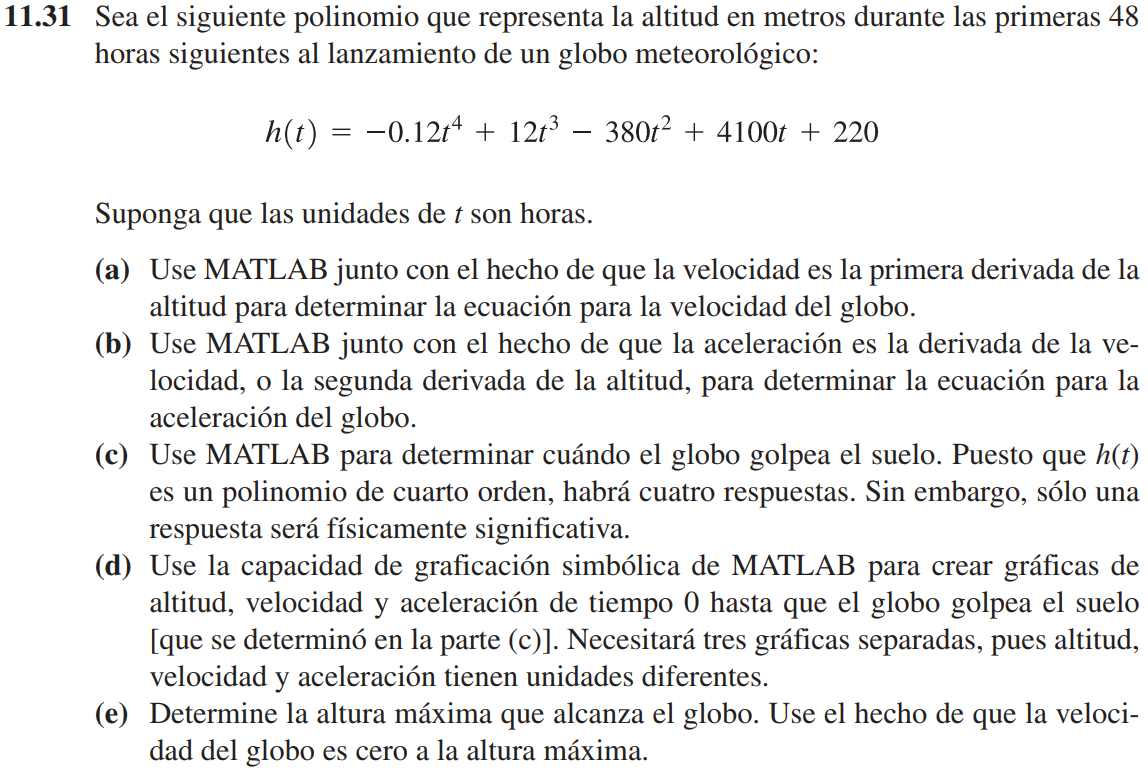

% Se define lo que se conoce.
clear

syms h(t)
h(t) = -.12*t^4 + 12*t^3 - 380*t^2 + 4100*t + 220

% Literal a, b y c.
v(t) = diff(h(t))
a(t) = diff(h(t),2)

impact = double(root(h));       % Raíces del polinomio.
idxTime = find(imag(impact) == 0 & real(impact) > 0);   % Busca el tiempo válido.
impactTime = impact(idxTime)    % Devuelve el tiempo válido.

% Literal d.
fplot(h(t),[0 impactTime])
    title 'Altura VS. Tiempo del globo meteorológico.'
    xlabel 'Tiempo, s'
    ylabel 'Altura, m'

fplot(v(t),[0 impactTime])
    title 'Velocidad VS. Tiempo del globo meteorológico.'
    xlabel 'Tiempo, s'
    ylabel 'Velocidad, m/s'

fplot(a(t),[0 impactTime])
    title 'Aceleración VS. Tiempo del globo meteorológico.'
    xlabel 'Tiempo, s'
    ylabel 'Aceleración, m/s^2'

% Literal e.
format bank
vRoot = double(root(v(t)));
hMax = double(max(subs(h(t),t,vRoot)))
format short